# Optimal design of experiments for atrazine degradation models

In this file, I show examples of how to read the energy distance (ED) outputs generated with the file "test_atrazine_EnergyDistances.m" for model variants M1 to M6. 

## Calling the Data

I am calling the file "Results_Energy_distances.mat" containing data from the energy distance results including models M1 to M6 for all proposed designs. It is a matrix 6x6x189 where 6 represents the models M1 to M6, and 189 the proposed designs. Details on the designs can be found in the excel file inside the "Proposed_experimental_designs" folder. 

load('Results_Energy_distances.mat')
Energy = E_dist;
load('ensemble.txt')
design = linspace(1,length(ensemble),length(ensemble));

## Pairwise energy distances

I am plotting the pairwise energy distances (expressed in standard deviation units) over the candidate design for models M1-M5 against M6. 

#### Based on chemical data and CO2

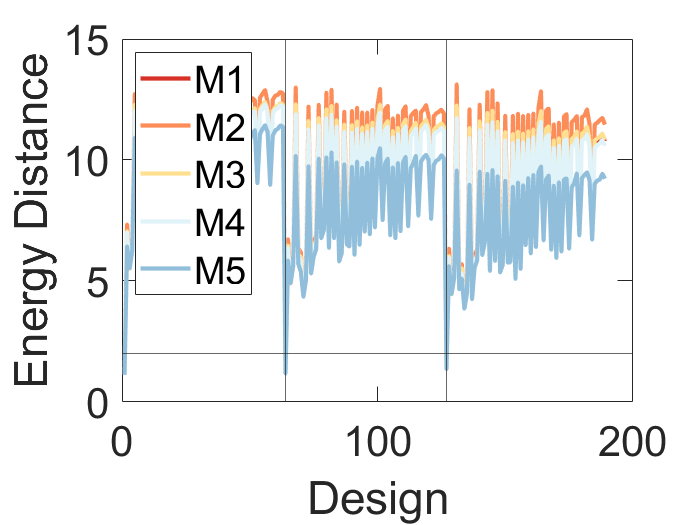

M1M1 = {};
M1M2 = {};
M1M3 = {};
M1M4 = {};
M1M5 = {};

for i = 1:length(E_dist)
    M1M1{end+1} = E_dist(6,1,i);
    M1M2{end+1} = E_dist(6,2,i);
    M1M3{end+1} = E_dist(6,3,i);
    M1M4{end+1} = E_dist(6,4,i);
    M1M5{end+1} = E_dist(6,5,i);
end

% From cell to matrix %

M1M1c = cell2mat(M1M1);
M1M2c = cell2mat(M1M2);
M1M3c = cell2mat(M1M3);
M1M4c = cell2mat(M1M4);
M1M5c = cell2mat(M1M5);

% Plotting %

figure(6)
A = plot(design,M1M1c,'LineWidth',2.5,'Color',[215,48,39]/255); 
hold on
B = plot(design,M1M2c,'LineWidth',2.5,'Color',[252,141,89]/255); 
C = plot(design,M1M3c,'LineWidth',2.5,'Color',[254,224,144]/255); 
D = plot(design,M1M4c,'LineWidth',2.5,'Color',[224,243,248]/255); 
E = plot(design,M1M5c,'LineWidth',2.5,'Color',[145,191,219]/255); 
G = yline(2);
H = xline(64);
I = xline(127);
box on
xlabel('Design'); 
ylabel('Energy Distance'); 
ylim([0 15])
legend([A B C D E],'M1','M2','M3','M4','M5','Location','northwest')
set(gca,'FontSize',25,'TickLength',[0.030 0.015])
hold off

####  Based on chemical data, CO2 and biomass

load('Results_Energy_distances_bio.mat')
design = linspace(1,length(E_dist),length(E_dist));
Energy = E_dist;

I am plotting the pairwise energy distances (expressed in standard deviation units) over the candidate design for models M1-M3 against M4.

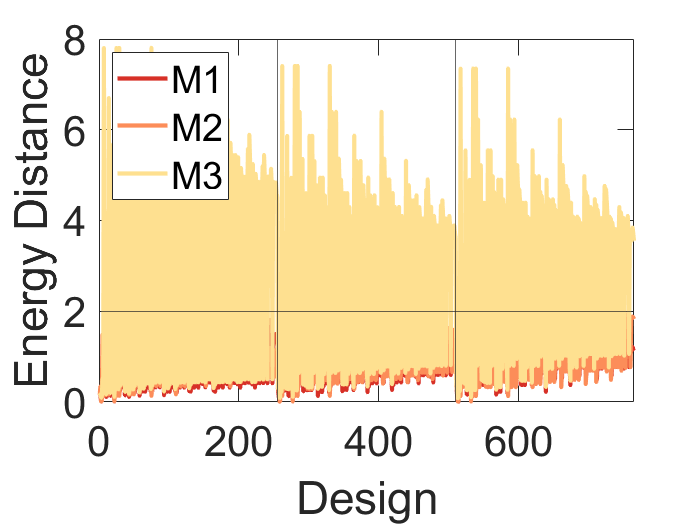

M1M1 = {};
M1M2 = {};
M1M3 = {};
M1M4 = {};

for i = 1:length(E_dist)
    M1M1{end+1} = E_dist(4,1,i);
    M1M2{end+1} = E_dist(4,2,i);
    M1M3{end+1} = E_dist(4,3,i);
    M1M4{end+1} = E_dist(4,4,i);
end

% From cell to matrix %

M1M1c = cell2mat(M1M1);
M1M2c = cell2mat(M1M2);
M1M3c = cell2mat(M1M3);
M1M4c = cell2mat(M1M4);

% Plotting %

figure(4)
A = plot(design,M1M1c,'LineWidth',2.5,'Color',[215,48,39]/255); 
hold on
B = plot(design,M1M2c,'LineWidth',2.5,'Color',[252,141,89]/255); 
C = plot(design,M1M3c,'LineWidth',2.5,'Color',[254,224,144]/255); 
box on
xlabel('Design'); 
ylabel('Energy Distance'); 
ylim([0 8])
G = yline(2);
H = xline(255);
I = xline(510);
legend([A B C],'M1','M2','M3','Location','northwest')
set(gca,'FontSize',25,'TickLength',[0.030 0.015])
hold off

####  Based on chemical data, CO2 and NI

load('Results_Energy_distances_NI.mat')
design = linspace(1,length(E_dist),length(E_dist));

I am plotting the pairwise energy distances (expressed in standard deviation units) over the candidate design for models M1-M2 against M3.

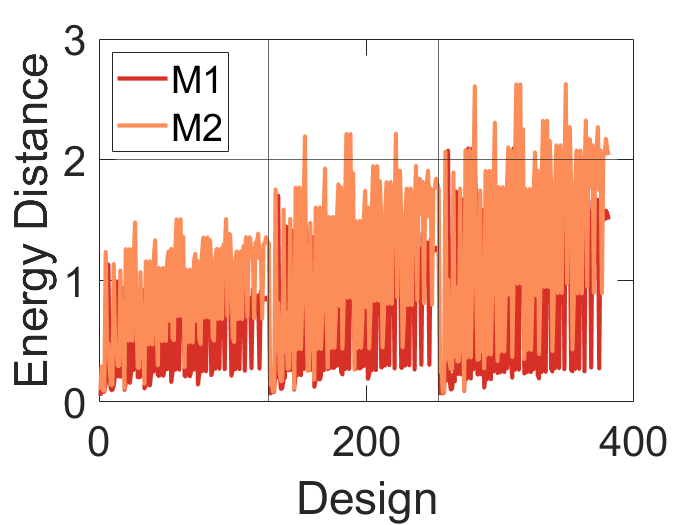

% M3 to others %

M1M1 = {};
M1M2 = {};
M1M3 = {};

for i = 1:length(E_dist)
    M1M1{end+1} = E_dist(3,1,i);
    M1M2{end+1} = E_dist(3,2,i);
    M1M3{end+1} = E_dist(3,3,i);
end

% From cell to matrix %

M1M1c = cell2mat(M1M1);
M1M2c = cell2mat(M1M2);
M1M3c = cell2mat(M1M3);

% Plotting %

figure(3)
A = plot(design,M1M1c,'LineWidth',2.5,'Color',[215,48,39]/255); 
hold on
B = plot(design,M1M2c,'LineWidth',2.5,'Color',[252,141,89]/255); 
box on
xlabel('Design'); 
ylabel('Energy Distance'); 
ylim([0 3])
G = yline(2);
H = xline(127);
I = xline(254);
legend([A B],'M1','M2','Location','northwest')
set(gca,'FontSize',25,'TickLength',[0.030 0.015])
hold off

#### Based on chemical data, CO2 and NE

load('Results_Energy_distances_NE.mat')
design = linspace(1,length(E_dist),length(E_dist));

I am plotting the pairwise energy distances (expressed in standard deviation units) over the candidate design for models M1-M2 against M4.

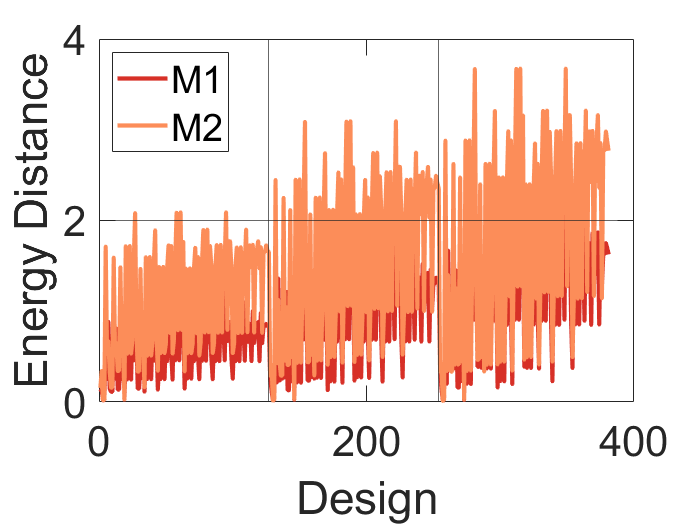

M1M1 = {};
M1M2 = {};
M1M4 = {};

for i = 1:length(E_dist)
    M1M1{end+1} = E_dist(3,1,i);
    M1M2{end+1} = E_dist(3,2,i);
    M1M4{end+1} = E_dist(3,3,i);
end

% From cell to matrix %

M1M1c = cell2mat(M1M1);
M1M2c = cell2mat(M1M2);
M1M4c = cell2mat(M1M4);

% Plotting %

figure(3)
A = plot(design,M1M1c,'LineWidth',2.5,'Color',[215,48,39]/255); 
hold on
B = plot(design,M1M2c,'LineWidth',2.5,'Color',[252,141,89]/255); 
box on
xlabel('Design'); 
ylabel('Energy Distance'); 
ylim([0 4])
G = yline(2);
H = xline(127);
I = xline(254);
legend([A B],'M1','M2','Location','northwest')
set(gca,'FontSize',25,'TickLength',[0.030 0.015])
hold off